# Segmentation U-Net

Team:

- **Maxine Annel Pacheco Ramírez A01551933**

- **Dacia Martínez Díaz A01733799**

- **Kristen Aideé Pérez Alvarez A00829551**

- **Allison Hernández Sánchez A01366543**

1) Create a U-Net network with an encoder-decoder depth of 3

clear all

%A = imread("IMG_3684.JPG")
imageSize = [480 640 3]; % En este vector pusimos las dimensiones de la imágen a analizar
numClasses = 5; % Se seleccionan 5 clases
Name = 'EncoderDepth'; 
Value = 3; %Este es el valor que se le da al encoder depth

lgraph = unetLayers(imageSize,numClasses,Name,Value) %Asignamos el output de unetLayers a la variable 

lgraph =   LayerGraph with properties:

         Layers: [46×1 nnet.cnn.layer.Layer]
    Connections: [48×2 table]
     InputNames: {'ImageInputLayer'}
    OutputNames: {'Segmentation-Layer'}


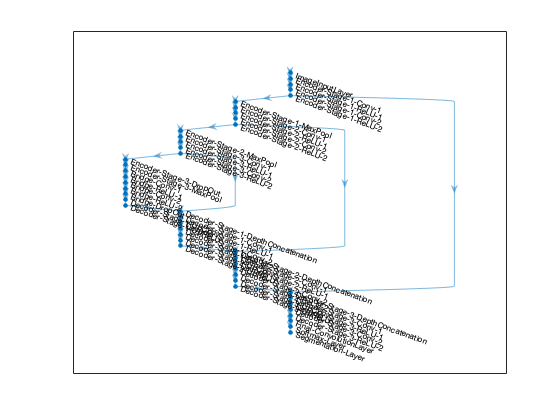

% lgraph y poder crear el plot

plot(lgraph) %Obtener en un plot las respuestas de lgraph

2) Train U-Net for semantic segmentation

%Load the images and pixel labels that you are going to use for training in the workspace. 
%For this excersie the images are of size 32x32 and we are working with two classes.

dataSetDir = fullfile(toolboxdir('vision'),'visiondata','triangleImages');
imageDir = fullfile(dataSetDir,'trainingImages');
labelDir = fullfile(dataSetDir,'trainingLabels');

%reate both, an imageDatastore object and a pixelLabelDatastore object to store the 
%training images and ground truth pixel labels, respectively.

imds = imageDatastore(imageDir); 

classNames = ["triangle","background"];
labelIDs   = [255 0];

% Create a pixelLabelDatastore object to store the ground truth pixel 
% labels for the training images.
pxds = pixelLabelDatastore(labelDir,classNames,labelIDs);

%% Crating the U-Net network
imageSize2 = [32 32];
numClasses2 = 2;
%WE CREATE THE UNET

lgraph2 = unetLayers(imageSize2, numClasses2)

lgraph2 =   LayerGraph with properties:

         Layers: [58×1 nnet.cnn.layer.Layer]
    Connections: [61×2 table]
     InputNames: {'ImageInputLayer'}
    OutputNames: {'Segmentation-Layer'}


ds = combine(imds,pxds); % Datastore for training the network.

%% Training options
%We played a little bit with the parameters to look for the most apropiated
%number of max epochs and how this affects the accuracy.

options = trainingOptions('sgdm', ...
    'InitialLearnRate',1e-3, ...
    'MaxEpochs',20, ...
    'VerboseFrequency',10);

%% Train the network
net = trainNetwork(ds,lgraph2,options)

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:14 |       42.16% |       5.7818 |          0.0010 |
|      10 |          10 |       00:02:04 |       95.13% |       0.4988 |          0.0010 |
|      20 |          20 |       00:04:25 |       96.69% |       0.2265 |          0.0010 |
|========================================================================================|


net =   DAGNetwork with properties:

         Layers: [58×1 nnet.cnn.layer.Layer]
    Connections: [61×2 table]
     InputNames: {'ImageInputLayer'}
    OutputNames: {'Segmentation-Layer'}


What is the most appropriate number of max epochs you can use? Why?

R: El número de epochs más apropiado es 20 ya que se tiene una precisión mayor, siendo esta de 96.69% y se pierde menos infromación (0.2265).

How did the learning rate affect the accuracy?

R: Mientras más pequeño sea el learning rate, la precisión disminuye.